E = 7*10^10;
rho = 2750;
L = 340;
b = 22;
t = 2;
S = b * t;
I =  (b*t^3)/12;
nel = 10;
nn = nel + 1; % nombre noeuds = ndegliberté
l0 = L / nel;
kmax = L/l0;
c0 = sqrt(E/rho);%célérité dans lma matière

mc = [2 1 ; 1 2] * (rho*S*l0/6);
md = [3 0 ; 0 3] * (rho*S*l0/6);
k = [1 -1 ; -1 1] * (E*S/l0);

%make M mass matrix
M = zeros(nn,nn);
%assamble M
for el = 1:nn-1; % boucle sur les éléments
    M(el:el+1,el:el+1) = mc + M(el:el+1,el:el+1);
end
disp(M / (rho*S*l0/6)); %display only coeficients in order to check if is good

     2     1     0     0     0     0     0     0     0     0     0
     1     4     1     0     0     0     0     0     0     0     0
     0     1     4     1     0     0     0     0     0     0     0
     0     0     1     4     1     0     0     0     0     0     0
     0     0     0     1     4     1     0     0     0     0     0
     0     0     0     0     1     4     1     0     0     0     0
     0     0     0     0     0     1     4     1     0     0     0
     0     0     0     0     0     0     1     4     1     0     0
     0     0     0     0     0     0     0     1     4     1     0
     0     0     0     0     0     0     0     0     1     4     1
     0     0     0     0     0     0     0     0     0     1     2





%make K stiffness matrix 
K = zeros(nn,nn);
%assamble K
for el = 1:nn-1;
    K(el:el+1,el:el+1) = k + K(el:el+1,el:el+1);
end
disp(K / (E*S/l0)); %display only coeficients in order to check if is good

     1    -1     0     0     0     0     0     0     0     0     0
    -1     2    -1     0     0     0     0     0     0     0     0
     0    -1     2    -1     0     0     0     0     0     0     0
     0     0    -1     2    -1     0     0     0     0     0     0
     0     0     0    -1     2    -1     0     0     0     0     0
     0     0     0     0    -1     2    -1     0     0     0     0
     0     0     0     0     0    -1     2    -1     0     0     0
     0     0     0     0     0     0    -1     2    -1     0     0
     0     0     0     0     0     0     0    -1     2    -1     0
     0     0     0     0     0     0     0     0    -1     2    -1
     0     0     0     0     0     0     0     0     0    -1     1



%CASE : Clamped-free rod

% solve for w, natural frequencies of the barsm.
% USING EIG from MATLAB:

K = K(2:end, 2:end);
M = M(2:end, 2:end);
[u,wnDiag] = eig(K,M);
wnEig = sqrt(diag(wnDiag));
disp(wnEig);

   23.3330
   70.5757
  119.5587
  171.4522
  227.3373
  287.8794
  352.4959
  417.6653
  474.6368
  509.3267





% USING THERORY :

%x= 0 => U=0
%x = L => U' = 0 (deformation =0)
%
% on applique les CLs, cela donne =>
% Csin(0) + Dcos(0) = 0 => d = 0
% U'(L) = 0 = (w/c0)C*cos(wL/c0)
% ommiting trivial solution w = 0  we get the equation :
% w = (c0/L)(2k -1)(pi/2)

% We go through k = 1  to 10 to computute 10 first mode
wnTh = [0 0 0 0 0 0 0 0 0 0];
for k = 1:10; % boucle sur les éléments
    wnTh(k) = (c0/L)*(2*k-1)*(pi/2);
end

disp(wnTh);

   23.3090   69.9270  116.5450  163.1630  209.7810  256.3990  303.0170  349.6350  396.2530  442.8710



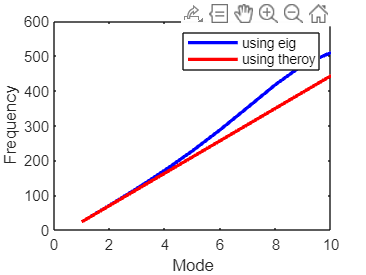


% We notice a difference between theroy and eig from matlab
% We will now plot the diffrence between the two
x = 1:10;
figure;
% Plot the first line in blue
plot(x, wnEig, 'b', 'LineWidth', 2);
hold on;
% Plot the second line in red
plot(x, wnTh, 'r', 'LineWidth', 2);

xlabel('Mode');
ylabel('Frequency');
legend('using eig', 'using theroy');

hold off;

%CASE 2

% solve for w, natural frequencies of the barsm.
% USING EIG from MATLAB:

%REMAKE MATRIX

%make M mass matrix
M = zeros(nn,nn);
%assamble M
for el = 1:nn-1; % boucle sur les éléments
    M(el:el+1,el:el+1) = mc + M(el:el+1,el:el+1);
end
disp(M / (rho*S*l0/6)); %display only coeficients in order to check if is good


%make K stiffness matrix 
K = zeros(nn,nn);
%assamble K
for el = 1:nn-1;
    K(el:el+1,el:el+1) = k + K(el:el+1,el:el+1);
end
disp(K / (E*S/l0)); %display only coeficients in order to check if is good

K = K(2:end, 2:end);
M = M(2:end, 2:end);
[u,wnDiag] = eig(K,M);
wnEig = sqrt(diag(wnDiag));
disp(wnEig);


% USING THERORY :

%x= 0 => U=0
%x = L => U' = 0 (deformation =0)
%
% on applique les CLs, cela donne =>
% Csin(0) + Dcos(0) = 0 => d = 0
% U'(L) = 0 = (w/c0)C*cos(wL/c0)
% ommiting trivial solution w = 0  we get the equation :
% w = (c0/L)(2k -1)(pi/2)

% We go through k = 1  to 10 to computute 10 first mode
wnTh = [0 0 0 0 0 0 0 0 0 0];
for k = 1:10; % boucle sur les éléments
    wnTh(k) = (c0/L)*(2*k-1)*(pi/2);
end

disp(wnTh);

% We notice a difference between theroy and eig from matlab
% We will now plot the diffrence between the two
x = 1:10;
figure;
% Plot the first line in blue
plot(x, wnEig, 'b', 'LineWidth', 2);
hold on;
% Plot the second line in red
plot(x, wnTh, 'r', 'LineWidth', 2);

xlabel('Mode');
ylabel('Frequency');
legend('using eig', 'using theroy');

hold off;